# **Logistic Regression Basics**

In [statistics](https://en.wikipedia.org/wiki/Statistics), the **logistic model** (or **logit model**) is a [statistical model](https://en.wikipedia.org/wiki/Statistical_model) that models the [log-odds](https://en.wikipedia.org/wiki/Log-odds) of an event as a [linear combination](https://en.wikipedia.org/wiki/Linear_function_(calculus)) of one or more [independent variables](https://en.wikipedia.org/wiki/Independent_variable). 


$$p(x)=\frac{1}{1+e^{-(x-\mu )/s} }$$


where *μ* is a [location parameter](https://en.wikipedia.org/wiki/Location_parameter) (the midpoint of the curve, where 𝑝(𝜇)=1/2) and *s* is a [scale parameter](https://en.wikipedia.org/wiki/Scale_parameter). This expression may be rewritten as:

$p(x)=\frac{1}{1+e^{-(\beta_0 +\beta_1 x)} }$ where $\beta_0 =-\mu /s$ and $\beta_1 =1/s$

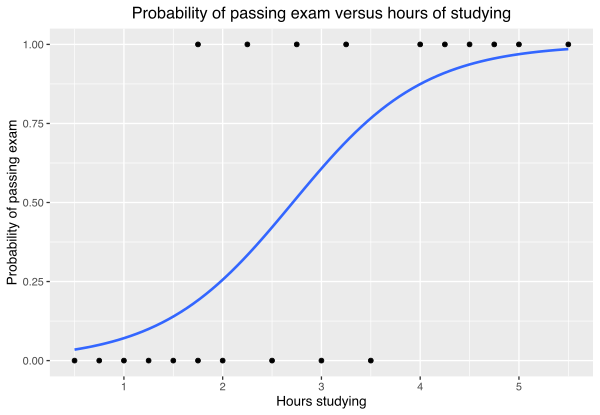

[https://commons.wikimedia.org/wiki/File:Exam_pass_logistic_curve.svg](https://commons.wikimedia.org/wiki/File:Exam_pass_logistic_curve.svg)

**Key Definitons**

Odds are the ratio of something happening


$$\mathrm{odds}=\left(\frac{p}{1-p}\right)=\frac{#\;\mathrm{of}\;\mathrm{successes}}{#\;\mathrm{of}\;\mathrm{failures}}$$
 

to make it symmetric we take the log odds


$$\log \left(\mathrm{odds}\right)=\log \left(\frac{p}{1-p}\right)=\mathrm{logit}\left(p\right)$$


### Synthetic Data

% Set random seed for reproducibility
rng(42);

% Generate synthetic data
n_samples = 1000;
X = randn(n_samples, 1);
true_intercept = -0.8;
true_coef = 2.5;
logit = true_intercept + true_coef * X;
prob = 1 ./ (1 + exp(-logit));
Y = binornd(1, prob);



### **Maximize the Log-Likelihood Function**


$$\mathrm{LL}\left(\mathrm{Beta}\right)=\sum_{i=1}^n y_i \beta x_i -\log \left(1+e^{\beta x_i } \right)$$


% Define the log-likelihood function
logLikelihood = @(params) -sum(Y .* log(1 ./ (1 + exp(-(params(1) + params(2) * X)))) + (1 - Y) .* log(1 - 1 ./ (1 + exp(-(params(1) + params(2) * X)))));

% Initial guess for the parameters
initial_params = [0, 0];

% Optimize the log-likelihood function
options = optimoptions('fminunc', 'Algorithm', 'quasi-newton', 'Display', 'iter');
[estimated_params, fval, exitflag, output] = fminunc(logLikelihood, initial_params, options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3          693.147                           328
     1           6          461.832     0.00304742            111  
     2           9          416.341              1           53.5  
     3          12          397.894              1           20.1  
     4          15          393.981              1           5.86  
     5          18          393.555              1          0.931  
     6          21          393.543              1         0.0526  
     7          24          393.543              1       0.000447  
     8          27          393.543              1       7.63e-05  

Local minimum found.

Optimization completed because the size of the gradient is less than
the val


% Display the results
disp('Estimated Parameters:');

Estimated Parameters:


disp(['Intercept: ', num2str(estimated_params(1))]);

Intercept: -0.80556


disp(['Coefficient for X: ', num2str(estimated_params(2))]);

Coefficient for X: 2.4007


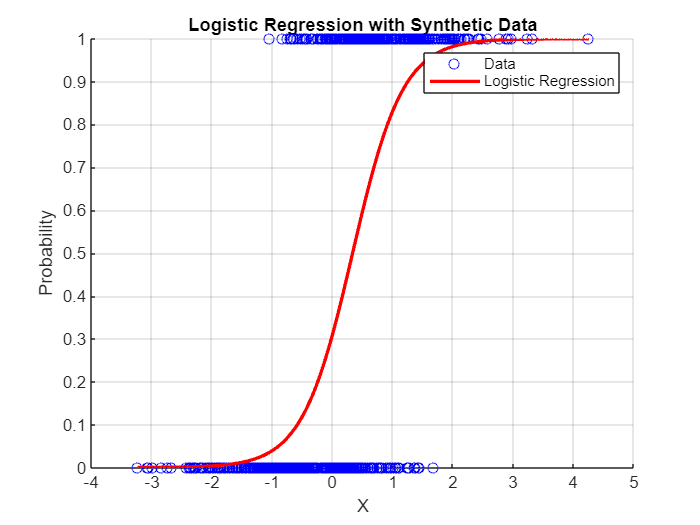


% Plot the data and the logistic regression curve
X_plot = linspace(min(X), max(X), 100)';
logit_plot = estimated_params(1) + estimated_params(2) * X_plot;
prob_plot = 1 ./ (1 + exp(-logit_plot));

figure;
scatter(X, Y, 'b', 'DisplayName', 'Data');
hold on;
plot(X_plot, prob_plot, 'r', 'LineWidth', 2, 'DisplayName', 'Logistic Regression');
xlabel('X');
ylabel('Probability');
title('Logistic Regression with Synthetic Data');
legend show;
grid on;